# Semi-Empirical Model Estimation:  Second Order Regression

System identification using empirical data. The predictions are aligned to the measured values through an optimizer that adjusts the empirical parameters to minimize a sum of squared error or sum of absolute values objective. The objective is to fit **empirical and physics-based predictions **to the data for a two heater model of the TC Lab. Parameters are adjusted to minimize the integral absolute error (IAE) between the model predicted values and the measured values.

### 
$$IAE_{model} = \sum_{i=0}^{n} \left| T_{1,meas,i} - T_{1,pred,i} \right| + \left| T_{2,meas,i} - T_{2,pred,i} \right|
$$


The optimizer is used to adjust the parameters and achieve alignment between the model and the measured values. Use input TC Lab data sets by colecting temperature data from sensors, make use of your reduced dynamic models (Heaters and sensors models). Observe models and obtain actual data coming from sensors, estimate outputs and reduce the difference between models and real-time response.

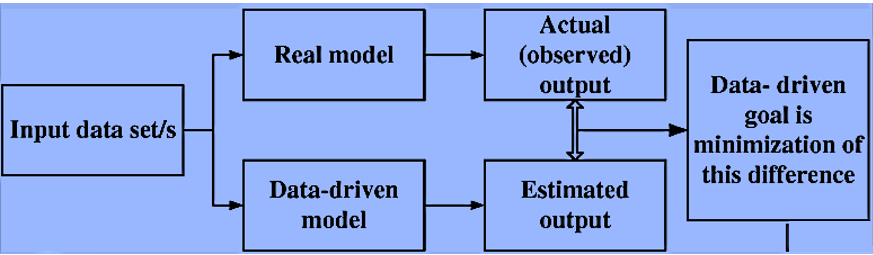

## 1. Regression MIMO System

Transient model between the two heater power outputs and the two temperature sensors. 

#### An energy balance describes the transient temperature response of heaters with temperature sensor

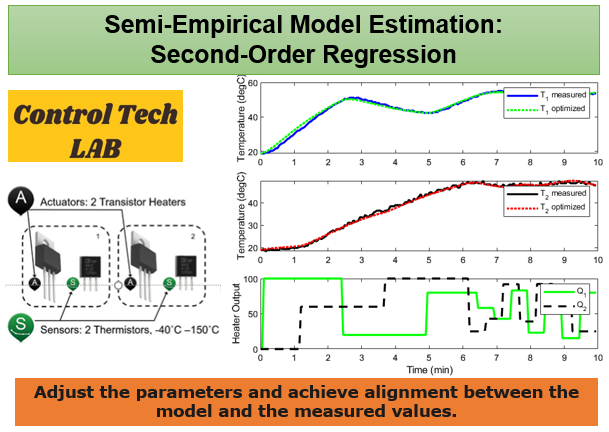

This model represents the energy balance equation with convective heat transfer, radiative heat transfer, and the heater energy inputs. 

#### 
$$mC_p \frac{dT_1}{dt} = UA(T_{\infty} - T_1) + \epsilon \sigma A_s (T_{\infty}^4 - T_1^4) + UA_s (T_2 - T_1) + \epsilon \sigma A_s (T_2^4 - T_1^4) + Q_1
$$


#### 
$$mC_p \frac{dT_2}{dt} = UA(T_{\infty} - T_2) + \epsilon \sigma A_s (T_{\infty}^4 - T_2^4) + UA_s (T_1 - T_2) + \epsilon \sigma A_s (T_1^4 - T_2^4) + Q_2
$$


## 2. Reduce model: Fit Second-Order Physics-based Model with Optimization

A second-order physics-based model starts with the [**dual heater energy balances**](http://apmonitor.com/pdc/index.php/Main/ArduinoModeling2) but neglects the radiation components. Here Q1 and Q2 are the heaters inputs. T12 is the system time constant and $T\infty \;$is the ambient temperature. K1, K2, K3 are unknown parameters and DT=T2-T1.

#### Heaters' reduced model


$$T_{12} \frac{dT_{1}}{dt}+( T_{1}-T_{\infty})  = K_{3} DT + K_{1}Q_{1} 
 
$$



$$T_{12} \frac{dT_{2}}{dt}+( T_{2}-T_{\infty})  = -K_{3} DT + K_{2}Q_{2} 
 
$$


#### Sensors' model

The heater and temperature sensor are assumed to be at the same temperature. You can assume that conduction is negligible and that the only heat transferred is through radiation to the surroundings or convection or radiation to the surrounding air or from the heater nearby. The heaters are initially off and the heaters and sensors are initially at ambient temperature. $\tau_c \;$is the time contant of the sensor dynamics. 

#### 
$$\tau_c \frac{dT_{C1}}{dt} = T_1 - T_{C1}
$$


#### 
$$\tau_c \frac{dT_{C2}}{dt} = T_2 - T_{C2}
$$


## 3. Parameter Regression: **Using the **APMonitor **Server for Real-time**

The APMonitor Modeling Language is optimization software for mixed-integer and differential algebraic equations. It is coupled with large-scale solvers for linear, quadratic, nonlinear, and mixed integer programming. Modes of operation include data reconciliation, real-time optimization, dynamic simulation, and nonlinear predictive control. It is freely available through MATLAB, Python, or from a web browser interface. [http://byu.apmonitor.com](http://byu.apmonitor.com/)[/](http://byu.apmonitor.com/)

Remember we will need internet!

close all; clear all; clc
addpath('apm')

s = 'http://byu.apmonitor.com';  %% We will need internet
a = 'parameter_regression';

#### **We are loading experimental data coming from the TC Lab**

10 minute data collection period that includes rapid and slow asynchronous (staggered) steps of the heaters with varying magnitude and direction. Use this [video](https://studio.youtube.com/video/iTlENSZBxHw/edit) to see the data collection process.

#### Second order regression 

Clear application and load new model and data files 

apm(s,a,'clear all');
apm_load(s,a,'model.apm');
csv_load(s,a,'data.csv');

Estimation mode

apm_option(s,a,'apm.imode',5); % Dynamic estimation
apm_option(s,a,'apm.solver',3);  %Real time

Classify variables

apm_info(s,a,'FV','K1');
apm_info(s,a,'FV','K2');
apm_info(s,a,'FV','K3');
apm_info(s,a,'FV','tau12');
apm_info(s,a,'FV','tau3');
apm_info(s,a,'MV','Q1');
apm_info(s,a,'MV','Q2');
apm_info(s,a,'CV','TC1');
apm_info(s,a,'CV','TC2');


Set status on

apm_option(s,a,'K1.status',1);
apm_option(s,a,'K2.status',1);
apm_option(s,a,'K3.status',1);
apm_option(s,a,'tau12.status',1);
apm_option(s,a,'tau3.status',0);


Set feedback status on

apm_option(s,a,'Q1.fstatus',1);
apm_option(s,a,'Q2.fstatus',1);
apm_option(s,a,'TC1.fstatus',1);
apm_option(s,a,'TC2.fstatus',1);


Optimize parameters

output = apm(s,a,'solve');
disp(output)

apm 193.140.4.5_parameter_regression <br><pre> ----------------------------------------------------------------
 APMonitor, Version 1.0.1
 APMonitor Optimization Suite
 ----------------------------------------------------------------
 
 
 --------- APM Model Size ------------
 Each time step contains
   Objects      :            0
   Constants    :            1
   Variables    :           11
   Intermediates:            1
   Connections  :            0
   Equations    :            5
   Residuals    :            4
 
 Number of state variables:           4780
 Number of total equations: -         4776
 Number of slack variables: -            0
 ---------------------------------------
 Degrees of freedom       :              4
 
 **********************************************
 Dynamic Estimation with Interior Point Solver
 **********************************************
  
  
 Info: Exact Hessian

******************************************************************************
This program c

Retrieve solution

y = apm_sol(s,a);
z = y.x;

Optimized parameter values

K1 = apm_tag(s,a,'K1.newval');
K2 = apm_tag(s,a,'K2.newval');
K3 = apm_tag(s,a,'K3.newval');
tau12 = apm_tag(s,a,'tau12.newval');
tau3 = apm_tag(s,a,'tau3.newval');

Display values

disp(['K1:   ' num2str(K1)])

K1:   0.7235


disp(['K2:   ' num2str(K2)])

K2:   0.42225


disp(['K3:   ' num2str(K3)])

K3:   0.40065


disp(['tau12:   ' num2str(tau12)])

tau12:   211.018


disp(['tau3:   ' num2str(tau3)])

tau3:   15


Read data.csv file for plotting

data = csvread('data.csv',1);
t = data(:,1);
T1meas = data(:,4);
T2meas = data(:,5);

 Plot results

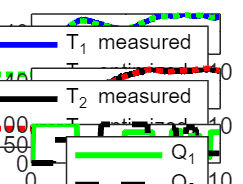

figure(1)
subplot(3,1,1)
plot(t/60,T1meas,'b-','LineWidth',2)
hold on
plot(z.time/60,z.tc1,'g:','LineWidth',2)
ylabel('Temperature (degC)')
legend('T_1 measured','T_1 optimized')

subplot(3,1,2)
plot(t/60,T2meas,'k-','LineWidth',2)
hold on
plot(z.time/60,z.tc2,'r:','LineWidth',2)
ylabel('Temperature (degC)')
legend('T_2 measured','T_2 optimized')

subplot(3,1,3)
plot(z.time/60,z.q1,'g-','LineWidth',2)
hold on
plot(z.time/60,z.q2,'k--','LineWidth',2)
ylabel('Heater Output')
legend('Q_1','Q_2')

xlabel('Time (min)')

It is a work by